% Plot graphs
Plot = false;
% Save praphs
Save_graph = true;

% Determine where your m-file's folder is
folder = fileparts(which("opt_problem.mlx"));
% Add that folder plus all subfolders to the path
addpath(genpath(folder));

#### GFDM parameters.

gfdm = struct;
gfdm.K = 5; % Subcarriers
gfdm.M = 4; % Subsymbols

gfdm.K_on = 5;
gfdm.M_on = 5;

fs = 0;
% gfdm.K = K;
% gfdm.M = M;

SEM = "802.11ac";
Channel = 20; % Channel bandwidth (MHz)
fs_UB = 1.5*Channel;
gfdm.rms = 0; % root mean square (rms) delay spread (ns)

uti_threshold =  0.55; % Utilize rate threshold
rc_beta = 0.1; % RC filter beta

fs_criteria = 0.1; % Bisection stop criteria

gfdm = GFDM_init(gfdm);

D = gfdm.D;

Normalized frequency $fT_s = \frac{f}{f_s}$ and normalized frequency interval $\Delta fT_s
$

delta_fTs = 0.01;
fTs_limit = (1+rc_beta)/2;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(fTs_limit,fTs_limit)
    msg = 'normalized frequency sampling interval delta_fTs can not equally spaces fTs_range';
    error(msg);
end

fTs_range = [0 fTs_limit];
fTs = -fTs_range(2):delta_fTs:fTs_range(2);

Interpolation filter $P(f)$

P = rc_filter(delta_fTs, fTs_range, rc_beta);

start = tic;
K_on = gfdm.K_on; M_on = gfdm.M_on;
KonMon = K_on * M_on;

gfdm.CP = ceil(gfdm.rms*fs*1e-3);
R_max = (KonMon/(D+gfdm.CP)) * fs;

N_CP = gfdm.CP;
uti_rate = KonMon/D;

S_sol = Dottorro(gfdm, fs, Channel, P, SEM, fTs);

total_time = duration([0, 0, toc(start)]);

fprintf('============== Final solution ==============\n');
fprintf("K: %d, M: %d, D: %d \n", gfdm.K, gfdm.M, D);
fprintf("K_on: %d, M_on: %d, N: %d \n", K_on, M_on, KonMon);
fprintf("R: %f, N_CP: %d\n",R_max, N_CP);
fprintf("Utility rate: %f, fs: %f \n", KonMon/D, fs);
fprintf('Total time: %s\n', total_time);
fprintf('============================================\n');

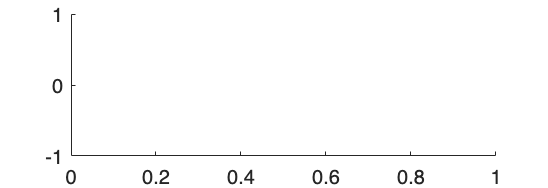

Error using xlim
Limits must be a 2-element vector of increasing numeric values.

Error in save_g (line 13)
xlim([0 D-1]);

% Assign S and g
g = S2g(S_sol);

gfdm.K_on = K_on; gfdm.M_on = M_on;
gfdm.CP = N_CP; gfdm.D_prime = gfdm.D + gfdm.CP;

% finer fTs
% delta_fTs = 0.01;
% fTs = -fTs_range(2):delta_fTs:fTs_range(2);
% P = rc_filter(delta_fTs, fTs_range, rc_beta);

switch SEM
    case "802.11ac"
        mask_dB = SEM_ac(fTs, fs, Channel);
    case "802.11b"
        mask_dB = SEM_b(fTs, fs, Channel);
end
mask_linear = db2pow(mask_dB);
psd_temp = zeros(size(P));
% G= g*(g');
% S_a_g = (P.^2) .* PSD_g(gfdm, g, fTs);
% S_a_G = (P.^2) .* PSD_big_G(gfdm, G, fTs);
S_a_S = PSD_S(gfdm, S_sol, fs, psd_temp, fTs, P);

if Plot
     
    plot_PSD(gfdm, S_a_S, mask_dB, fTs, Channel, R_max);
    plot_g(g);
end

if Save_graph
     save_PSD(gfdm, S_a_S, mask_dB, fTs, Channel, R_max);
     save_g(gfdm, g);
end